# Simulation of different cases

## General case example:

### Orbit, Time and Attitude parameters

In this section of the code, the following parameters are set: Orbit (with the 6 orbital parameters, RAAN defines the beta angle), the date of the simulation and what is the pointing of the satellite. the pointing mode can be set as:

- MODE = 1: "orbital" Reference quaternion is aligned with ORF. 

- MODE = 2: "sun-aero" Reference quaternion is such that x is aligned with velocity and z is aligned as best as possible with the sun direction to maximize the power generation 

- MODE = 3: "sun pointing" Reference quaternion is such that z is aligned with with the sun direction to maximize the power generation and x is aligned as best as possible with the velocity direction. 

- MODE = 4: "aero-drag" Reference quaternion is similar than in Case 1, but rotated 90° along the y axis, therefore, the reference quaternion is an attitude for 

- %maximizing the drag surface. 

- MODE = 5: "retrogade firing" Reference quaternion is similar than in Case 1, but rotated 180° along the z axis, therefore, the reference quaternion is an attitude for retrograde propulsion. 

- MODE = 6: Reference quaternion is static [1 0 0 0], but this time is the only case  where the state of the B-dot is enabled (1). 

- MODE = 7: Reference quaternion is a custom quaternion that has to be defined by the user as an input to the mission block. 

- MODE = 8: Reference quaternion is similar to case 3, but with the degree of freedom it tries to align to the nadir direction to maximize the drag surface.

- MODE = 9: Same as #2, but there is a rotation of 45 degrees to maximize power generation (panels +X, +Y). An offset can be included here, this offset can be manually turned off in the simulink diagram.

- MODE = 10: Same as #3, but there is a rotation of 45 degrees to maximize power generation (panels +X, +Y).

- MODE = 11: SLERP: a fraction "t" represents the linear interpolation between modes 9 an 10.

The conditions were set as follow:

clear all
close all

%Orbit: Initialisation of Keplerian parameters
orbit.a = 6671e3;       %semimajor axis [m] ~293km
orbit.e = 0.001;        %eccentricity
orbit.i = 51.64;        %inclination [degrees]
%orbit.O = 03;           %Right ascension of the right ascending node [degrees] 
orbit.O = 20;           %Right ascension of the right ascending node [degrees] 
orbit.o = 0;            %Argument of the perigee [degrees]                     
orbit.nu = 0;           %True anomaly [degrees]
% O =   0 10   20   30   40    50    60   70   80   90
% beta= 0 7.8  15.5 23   30.2  36.8  42.7 47.2 50.5 51.6
%Initialisation of date
date.year=2026;
date.month=3;
date.day=21;
date.hour=12;
date.minutes=0;
date.seconds=0;

%POINTING MODE
MODE = 9;   %"sun-aero" with side panels 45deg.  pointing mode
att.t = 0.4;  %interpolation fraction for MODE 11 only
att.angle_roll = pi/4;  %Rotated angle in roll for MODE 9, 10, 11
att.offset_axis = [1; 0; 0];    %error axis for MODE 9 only
att.offset_angle = 15*pi/180;   %error angle for MODE 9 only

% Ground Station parameters
GS.lat = 49.976;      %latitude in degrees
GS.long = 9.968;      %longitude in degrees
GS.h = 177;           %altitude in meters
% GS.alt_orbit=a*1000-R_earth;
% d_0=(sqrt((R_earth+alt_orbit)^2-R_earth^2))/1000;

### Power Generation

In this section is where the power generation conditions are set.

%Power Generation
SP.Pcell = 2.32*0.436;    %Peak power generated by a cell [W], no conversion efficiency
SP.PsaX = 7 * SP.Pcell;   %Peak power generation +Z side[W] 7 solar cells
SP.Psa_X = 0 * SP.Pcell;  %Peak power generation -Z side[W] 0 solar cells
SP.PsaY = 7 * SP.Pcell;   %Peak power generation +Z side[W] 7 solar cells
SP.Psa_Y = 7 * SP.Pcell;  %Peak power generation -Z side[W] 7 solar cells

### Thermal considerations solar panel

In this section is where the power power flux conditions are set.

%Infrared 
orbit.Re = 6378e3;          %Earth radius [km]
SP.FF = (orbit.Re/orbit.a)^2;  % Form Factor
SP.Pir = 1367*(1-0.3)/4*SP.FF;    % Peak flux IR from Earth [W/m^2]
SP.PirX = 1 * SP.Pir;   %Peak flux IR +X side [W/m^2] 7 solar cells
SP.Pir_X = 0 * SP.Pir;  %Peak flux IR -X side [W/m^2] 0 solar cells
SP.PirY = 1 * SP.Pir;   %Peak flux IR +Y side [W/m^2] 7 solar cells
SP.Pir_Y = 1 * SP.Pir;  %Peak flux IR -Y side [W/m^2] 7 solar cells

%Albedo
SP.Palb = 1367*0.3*SP.FF;   % Peak flux Albedo from Earth [W/m^2]
SP.PalbX = 1 * SP.Palb;   %Peak flux albedo +X side [W/m^2] 7 solar cells
SP.Palb_X = 0 * SP.Palb;  %Peak flux albedo -X side [W/m^2] 0 solar cells
SP.PalbY = 1 * SP.Palb;   %Peak flux albedo +Y side [W/m^2] 7 solar cells
SP.Palb_Y = 1 * SP.Palb;  %Peak flux albedo -Y side [W/m^2] 7 solar cells

### Battery Configuration

The battery configuration is 1S 4P, can be modified with Nbp (in parallel), Nbs (in series)

Bat.Cbat=2.6;           %Cell capacity in [Ah]
Bat.Nbs=1;              %Number of batteries in series
%Bat.Nbp=4;              %Number of batteries in parallel
Bat.Nbp=6;              %Number of batteries in parallel
Bat.C=Bat.Cbat*Bat.Nbp*3600;    %Battery Capacity for all parallel arrays [Ampere*sec]
%Power distribution efficiencies
Bat.eff_iBat=0.95;       %efficiency from Battery to load
Bat.eff_i1=0.95;         %efficiency PDU CH not regulated
Bat.eff_i2=0.95;         %efficiency PDU CH 3.3V
%Battery
Bat.DOD_0 = 0.05;       %initial DOD from 0 to 1
Batt.C1 = 7240;         %internal capacitance model Battery [F]
Batt.R2 = 0.01968;      %internal charging resistance model battery [Ohm]
Batt.SoC_0=1-Bat.DOD_0; %Initial SoC
%Charge/Discharge logic
Bat.I_BD_max= 5.2*Bat.Nbp;     %Maximum discharge current [A] approx. 2C rate
Bat.I_BC_max= -2.6*Bat.Nbp;     %Maximum charge current [A] approx. 1C rate

### Loads

Listed below all the loads

%System Margin
EPS.System_Margin = 0.1;    %10% system margin all loads

%EPS
EPS.eff_MPPT = 0.89;     %efficiency MPPT conversion
%EPS.P_eps = 0.11*2;      %internal power consumption 2xEPS [W]
EPS.P_eps = 0.05*Bat.Nbp/2;      %internal power consumption 3xEPS [W]
EPS.margin = 0.10;
EPS.otherlosses = 0.3;     %Loses in the power distribution path [W]

%Subsystem Loads
%OBC + Solar Panels
OBC.poweruC = 0.05;     %Required power OBC [W]
OBC.eff = 0.9;         %efficiency CH OBC
%OBC.powerPanel = 0.048;    %idle power consumption from 3 panels
OBC.powerPanel = 0.32;    %Power consumption from 3 panels
OBC.effPanel = 0.95;
OBC.power = OBC.poweruC/OBC.eff + OBC.powerPanel/OBC.effPanel;
OBC.margin = 0.10;      %margin OBC: 10%

%Thruster required power
OCS.n=2;
OCS.m=2;
OCS.pt_idle=0.125;      %0.125W according to latest ICD
OCS.pt_heat=8.5-0.125;  %8.5W heating for 10sec
OCS.pt_peak=4.2-0.125;  %Required power Thruster firing [W]
%OCS.t0=180*60;          %Time wait before first use of the Thruster;
OCS.t0=165*60;          %Time wait before first use of the Thruster;
OCS.t_n=300*60;         %time waiting between 2 firings, 'recharging' [seconds], 350 minutes
%OCS.t_m=09*60*60;       %time waiting between 2 sets of firings, [seconds], 3.8*2+t_n+t0 hours
OCS.t_m=11.33*60*60;       %time waiting between 2 sets of firings, [seconds], 3.8*2+t_n+t0 hours
OCS.d_h = 30;           %time heating thruster: in [s]
OCS.d_t = 6;            %seconds, total time of thrust (without heating of the thruster)
[OCS.t_thr,OCS.p_thr]=calc_thrust_power(OCS.pt_peak,OCS.pt_heat,OCS.pt_idle,...
    OCS.d_h, OCS.d_t, OCS.n, OCS.m, OCS.t0, OCS.t_n, OCS.t_m);
OCS.eff=0.95;
OCS.margin=0.05;        %Margin Thruster consumption: 10%

%ADCS
load("RWinfo.mat");     %loads power consumption measured by RW @5V
%P_ADC=0.463;          %power consumption by sensors and eq. at 3.3V
%P_ADC=2.063;          %power consumption by sensors and eq. at 3.3V
%ADCS.powerelec = 0.326 %old value
ADCS.powerelec = 0.47;      %power consumption by sensors and eq. at 3.3V
                            %according to measurements it is 270mW + 200mW SS
ADCS.effpowerelec = 0.9;
ADCS.power1 = ADCS.powerelec/ADCS.effpowerelec;
ADCS.margin1 = 0.05;

%RWA
ADCS.n = 4;
ADCS.m = 2;
ADCS.pc_idle = 0.00;       %Power comm idle: 0mW
ADCS.pc_half = 0.00;       %no heating
ADCS.pc_full = 1.2;        %Required power [W]
ADCS.t0_c = 140*60;        %Time wait before first use of the RWA;
ADCS.t_n = 80*60;          %time waiting between 2 transmission [seconds], 90 minutes
ADCS.t_m = 12.8*60*60;       %time waiting between 2 transmissions [seconds], 16 hours
ADCS.d_h = 1;              %heating/starting RW time in [s]
ADCS.d_f = 1349;           %seconds, total time of RWA activated
[ADCS.t_rw,ADCS.powerRWs]=calc_comm_power(ADCS.pc_idle,ADCS.pc_half,ADCS.pc_full, ...
    ADCS.d_h, ADCS.d_f, ADCS.n, ADCS.m, ADCS.t0_c, ADCS.t_n, ADCS.t_m);
[ADCS.sorted_t, ADCS.idx] = sort(ADCS.t_rw);
ADCS.sorted_p = ADCS.powerRWs(ADCS.idx);
[ADCS.unique_t, ia, ~] = unique(ADCS.sorted_t, 'stable');
ADCS.unique_p = ADCS.sorted_p(ia);
ADCS.t_rw = ADCS.unique_t;
ADCS.powerRWs = ADCS.unique_p;
ADCS.effRW = 0.95;
ADCS.marginRWs = 0.05;

%ADCS.powerRWs = 0.05;       %Reaction wheel power consumption average
% ADCS.p_idle = 0.0;          %Idle power consumption of RW
% ADCS.n = 5;                 %number of RW activations separated by small time
% ADCS.m = 2;                 %number of RW activations separated by large time
% ADCS.t0 = 145*60;           %time to wait before first RW activation (seconds)
% ADCS.t_n = 90*60;            %time between consecutive n RW activations (seconds)
% ADCS.t_m = 12*60*60;         %time between m groups of n RW activations (seconds)
% [ADCS.t_rw,ADCS.powerRWs] = calc_RW_power(ADCS.RWtime, ADCS.RWpwr, ADCS.p_idle, ADCS.n, ADCS.m, ADCS.t0, ADCS.t_n, ADCS.t_m);
% ADCS.effRW = 0.95;
% ADCS.marginRWs = 0.05;

%ADCS.powerMTQ = 0.33;      %MTQ power consmuption average?
ADCS.powerMTQ = 0.12;       %MTQ power consmuption average? guess: 25% at 337mW
ADCS.effMTQ = 0.90;
ADCS.marginMTQ = 0.1;

%GNSS
GPS.power = 0.132;      %Required power GPS [W]
GPS.eff = 0.95;         %efficiency CH 
GPS.margin = 0.10;      %margin GPS power consumption 10%

%when there is no contact, it is only sending beacons 3 packets per minute, 
% you can find duty cycle from it. When there is contact, you can assume 
% 50/50 rx/tx duty cycle. With these you can find daily average.
%COM UHF subsystem
UHF.n = 5;
UHF.m = 2;
%UHF.pc_idle = 0.22;       %Power comm idle: 32mW, only rx: 0.22W
UHF.pc_idle = ((60-3)*0.032+3*2.86)/60;       %Power comm idle: 32mW 57 sec
UHF.pc_access = (0.22+2.86)*0.5;
UHF.pc_half = 0.22;       %Required power Rx [W]
UHF.pc_full = 2.86;       %Required power Tx [W]
UHF.t0_c = 150*60;        %Time wait before first use of the UHF TRx;
UHF.t_n = 90*60;          %time waiting between 2 transmission [seconds], 90 minutes
UHF.t_m = 10.8*60*60;       %time waiting between 2 transmissions [seconds], 16 hours
UHF.d_h = 3*60;           %duration Rx in [s]
UHF.d_f = 3*60;           %seconds, duration Tx (without heating of the thruster)
[UHF.t_tx_UHF,UHF.p_tx_UHF]=calc_comm_power(UHF.pc_idle,UHF.pc_half,UHF.pc_full, ...
    UHF.d_h, UHF.d_f, UHF.n, UHF.m, UHF.t0_c, UHF.t_n, UHF.t_m);
[UHF.sorted_t, UHF.idx] = sort(UHF.t_tx_UHF);
UHF.sorted_p = UHF.p_tx_UHF(UHF.idx);
[UHF.unique_t, ia, ~] = unique(UHF.sorted_t, 'stable');
UHF.unique_p = UHF.sorted_p(ia);
UHF.t_tx_UHF = UHF.unique_t;
UHF.p_tx_UHF = UHF.unique_p;
UHF.eff = 0.95;         %efficiency CH COM
UHF.margin = 0.1;       %Margin UHF power 10%


% PAYLOAD
%processor + antenna on side panel -X
PL.n = 4;
PL.m = 2;
PL.pp_idle = 0.02;       %Interface board [W]
PL.pp_half = 7.84;       %processor power [W]
%PL.pp_full = 30.59;      %Required power Tx+Rx [W]
PL.pp_Tx = 30.59;
PL.pp_full = 38.40;      %Required power Tx+Rx [W]
PL.t0_p = 151*60;        %Time wait before first use of the Payload;
PL.t_n = 90*60;          %time waiting between 2 transmission [seconds], 90 minutes
PL.t_m = 12*60*60;       %time waiting between 2 transmissions [seconds], 20 hours
PL.d_h = 380;            %time using only processor: in [s]
PL.d_f = 153;            %seconds, total time of trx (with processor)
[PL.t_tx_S,PL.p_tx_S]=calc_comm_power(PL.pp_idle,PL.pp_half,PL.pp_full,... 
    PL.d_h, PL.d_f, PL.n, PL.m, PL.t0_p, PL.t_n, PL.t_m);

[PL.sorted_t, PL.idx] = sort(PL.t_tx_S);
PL.sorted_p = PL.p_tx_S(PL.idx);
[PL.unique_t, ia, ~] = unique(PL.sorted_t, 'stable');
PL.unique_p = PL.sorted_p(ia);
PL.t_tx_S=PL.unique_t;
PL.p_tx_S=PL.unique_p;
PL.eff=0.95;            %efficiency CH COM
PL.margin=0.05;          %Margin power consumption 5%


%FIPEX
FIPEX.P_op_fi=4.2;        %Required power heater/fipex [W], 
FIPEX.P_heat_fi=11;
FIPEX.t0_Fi=12*90*60;     %approx 12 orbits before start in [seconds]
%FIPEX.t0_Fi=12*90*60+48*60*60;     %approx 12 orbits + 2 days before start in [seconds]
FIPEX.tON_Fi=90*60;       %Duration of Fipex payload ON: 1 orbit in [seconds]
FIPEX.tend_Fi=24*60*60;   %end of cycle, 3 days, 1 activation per cycle
%FIPEX.tend_Fi=(24+48)*60*60;   %end of cycle, 3 days, 1 activation per cycle
FIPEX.P_idle_Fi=0;
FIPEX.p_Fi=[FIPEX.P_idle_Fi   FIPEX.P_idle_Fi   FIPEX.P_heat_fi   FIPEX.P_heat_fi  FIPEX.P_op_fi    FIPEX.P_op_fi       FIPEX.P_idle_Fi          FIPEX.P_idle_Fi];
FIPEX.t_Fi=[0           FIPEX.t0_Fi-21    FIPEX.t0_Fi-20    FIPEX.t0_Fi-1    FIPEX.t0_Fi      FIPEX.t0_Fi+FIPEX.tON_Fi  FIPEX.t0_Fi+FIPEX.tON_Fi+1    FIPEX.tend_Fi];
FIPEX.eff = 0.95;
FIPEX.margin = 0.1;

Listed below which loads are active

EN.Thr=1;           %Thruster Enabled=1, disabled=0
EN.OBC=1;           %OBC Enabled=1, disabled=0
EN.ADCS1=1;         %ADCS 3.3V Enabled=1, disabled=0
EN.RW=1;
EN.MTQ=1;
EN.UHF=1;           %TRx UHF enabled=1
EN.S=1;             %Payload Ka-band enabled=1
EN.GPS=1;           %GPS Enabled=1, disabled=0
EN.heat=1;          %Fipex Enabled=1, disabled=0

### Simulations

First set up the time:

%Duration of the simulation
Torb=2*pi*sqrt((orbit.a/1000)^3/(3.986004418E5)); %Orbit duration
%N_orbits = 150; %15 ~ 1 day, %31 ~ 2 days
N_orbits = 35; %15 ~ 1 day, %31 ~ 2 days
tsimulation = N_orbits*Torb;
delta_t = 1; %simulation time step (seconds)
TimeStep = delta_t; %just for some simulink block

The simulations are performed:

Power=sim('EPS_orbit_v5b');
timesec = Power.tout;
time=timesec/60;  %to plot in minutes
Pcollected = getdatasamples(Power.Psa1,(1:length(time)));
beta = getdatasamples(Power.beta,(1:length(time)));

### Payloads activation

%% first part
timesec = Power.tout;
time=timesec/60;  %to plot in minutes

el.ele00 = getdatasamples(Power.el00,(1:length(time)));
el.ele25 = getdatasamples(Power.el25,(1:length(time)));

% Detect rising edges (0 to 1 transitions)
el.rising_edges0 = find(diff(el.ele00) == 1) + 1;
el.rising_edges25 = find(diff(el.ele25) == 1) + 1;

% Detect falling edges (1 to 0 transitions)
el.falling_edges0 = find(diff(el.ele00) == -1) + 1;
el.falling_edges25 = find(diff(el.ele25) == -1) + 1;

%A: To activate all the payloads according to the elevation condition
PL.active=zeros(1,length(time));
ADCS.RWactive=zeros(1,length(time));
for i=1:length(el.rising_edges25)       %number of 25 deg access
    for k=1:length(el.rising_edges0)
        %only if the elevation is more than 25 deg, the PL is activated:
        if el.rising_edges25(i) < el.falling_edges0(k) && el.rising_edges25(i) > el.rising_edges0(k)
            %PL link activated
            PL.active(el.rising_edges0(k):el.falling_edges0(k)) = 1;
            %Also RW 10 minutes before for 20 minutes
            ADCS.RWactive (el.rising_edges0(k)-600:el.rising_edges0(k)+749) = 1.2; %only has to be >0.5 any value is ok
        end
    end
end

% %B: To activate the payloads according to the number of contact
% PL.active=zeros(1,length(time));
% ADCS.RWactive=zeros(1,length(time));
% for i=1:length(el.rising_edges25)       %number of 25 deg access
%     for k=1:length(el.rising_edges0)
%         %only if the elevation is more than 25 deg, the PL processor is activated:
%         if el.rising_edges25(i) < el.falling_edges0(k) && el.rising_edges25(i) > el.rising_edges0(k)
%             %PL link activated
%             PL.active(el.rising_edges0(k):el.falling_edges0(k)) = 1;
%             if mod(i,4) == 0 %ADDED to say that the fourth access goes to zero 
%                 PL.active(el.rising_edges0(k):el.falling_edges0(k)) = 0;
%             end
%             %Also RW 10 minutes before for 20 minutes
%             ADCS.RWactive (el.rising_edges0(k)-600:el.rising_edges0(k)+749) = 1.2; %only has to be >0.5 any value is ok
%             if mod(i,4) == 0 %ADDED to say that the fourth access goes to zero 
%                 ADCS.RWactive (el.rising_edges0(k)-600:el.rising_edges0(k)+749) = 0; %only has to be >0.5 any value is ok
%             end
%         end
%     end
% end


% %C: To activate the payloads according to the number of contact
% PL.active=zeros(1,length(time));
% ADCS.RWactive=zeros(1,length(time));
% for i=1:length(el.rising_edges25)       %number of 25 deg access
%     for k=1:length(el.rising_edges0)
%         %only if the elevation is more than 25 deg, the PL processor is activated:
%         if el.rising_edges25(i) < el.falling_edges0(k) && el.rising_edges25(i) > el.rising_edges0(k)
%             %PL link activated
%             PL.active(el.rising_edges0(k):el.falling_edges0(k)) = 1;
%             if mod(i,3) == 0 %ADDED to say that the third access goes to zero 
%                 PL.active(el.rising_edges0(k):el.falling_edges0(k)) = 0;
%             end
%             %Also RW 10 minutes before for 20 minutes
%             ADCS.RWactive (el.rising_edges0(k)-600:el.rising_edges0(k)+749) = 1.2; %only has to be >0.5 any value is ok
%             if mod(i,3) == 0 %ADDED to say that the third access goes to zero 
%                 ADCS.RWactive (el.rising_edges0(k)-600:el.rising_edges0(k)+749) = 0; %only has to be >0.5 any value is ok
%             end
%         end
%     end
% end


% plot(time,PL.active)
% hold on
% plot(time,ADCS.RWactive)

E=sim('EPS_sim_test_v8b');

Processing data:

% timesec = E.tout;
% time=timesec/60;  %to plot in minutes
DOD = getdatasamples(E.DOD,(1:length(time)));
Vbat = getdatasamples(E.Vbat,(1:length(time)));
Ibat = getdatasamples(E.Ibat,(1:length(time)));
SOC = 100*(1 - DOD);
%Pcollected = getdatasamples(Power.Psa1,(1:length(time)));
%beta = getdatasamples(Power.beta,(1:length(time)));
Ploads = getdatasamples(E.LOAD,(1:length(time)));
Ploadsingle = getdatasamples(E.LOADS,(1:length(time)));

%get charge and discharge currents
ibc=zeros(length(time),1);
ibd=zeros(length(time),1);
for i=1:length(time)
    if Ibat(i)>0
        ibc(i,1)=0;
        ibd(i,1)=Ibat(i);
    end
    if Ibat(i)<0
        ibc(i,1)=-Ibat(i);
        ibd(i,1)=0;
    end
end

%Mean values
MEAN.mean_power_loads_OCS=mean(Ploadsingle(:,1));
MEAN.mean_power_loads_ADCS=mean(Ploadsingle(:,2));
MEAN.mean_power_loads_UHF=mean(Ploadsingle(:,3));
MEAN.mean_power_loads_OBC_panels=mean(Ploadsingle(:,4));
MEAN.mean_power_loads_GNSS=mean(Ploadsingle(:,5));
MEAN.mean_power_loads_FIPEX=mean(Ploadsingle(:,6));
MEAN.mean_power_loads_Ka=mean(Ploadsingle(:,7));
MEAN.mean_power_loads_EPS_losses=mean(Ploadsingle(:,8));
MEAN.mean_power_loads_TOTAL=MEAN.mean_power_loads_OCS + MEAN.mean_power_loads_ADCS+...
    MEAN.mean_power_loads_UHF + MEAN.mean_power_loads_OBC_panels+...
    MEAN.mean_power_loads_GNSS + MEAN.mean_power_loads_FIPEX+...
    MEAN.mean_power_loads_Ka + MEAN.mean_power_loads_EPS_losses;

#### Plots

The plots show the following:

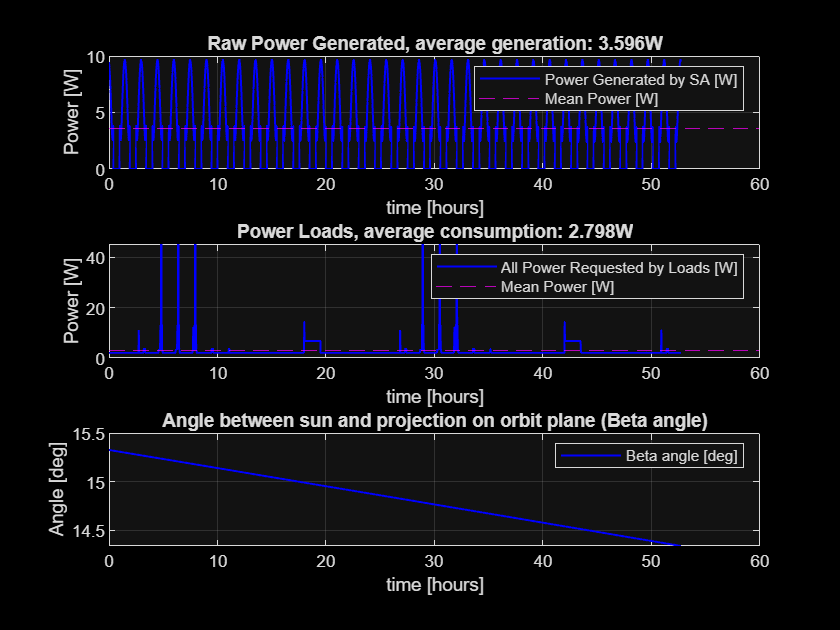

close all
time=timesec/3600;  %to plot in minutes
mean_power_collected=mean(Pcollected);
mean_power_loads=mean(Ploads);
figure(9)
%set(gcf,'color','w');
%set(gca,'color','w');
%set(gcf,'InvertHardcopy','off'),
set(gcf,'color','black');
    subplot(3,1,1)
        plot(time,Pcollected,'b','LineWidth',1)
        hold on;
        yline(mean_power_collected,'m--')
        legend('Power Generated by SA [W]','Mean Power [W]')
        %title('Power Generated')
        title(['Raw Power Generated, average generation: ',num2str(mean_power_collected),'W'])
        ylabel('Power [W]')
        xlabel('time [hours]')
        grid on
    subplot(3,1,2)
        %plot(time,Ploads,'b','LineWidth',1)
        Ploads_1d = squeeze(Ploads);
        plot(time,Ploads_1d,'b','LineWidth',1)
        hold on;
        yline(mean_power_loads,'m--')
        legend('All Power Requested by Loads [W]','Mean Power [W]')
        if EN.Thr==1
            %title(['Power Loads with Thruster Duty Cycle: ',num2str(Duty_cycle),'%'])
            title(['Power Loads, average consumption: ',num2str(mean_power_loads),'W'])
        else
            title('Power Loads')
        end
        ylabel('Power [W]')
        xlabel('time [hours]')
        %ylim([0,22])
        grid on
    subplot(3,1,3)
        plot(time,beta,'b','LineWidth',1)
        hold on;
        legend('Beta angle [deg]')
        title('Angle between sun and projection on orbit plane (Beta angle)')
        ylabel('Angle [deg]')
        xlabel('time [hours]')
        grid on

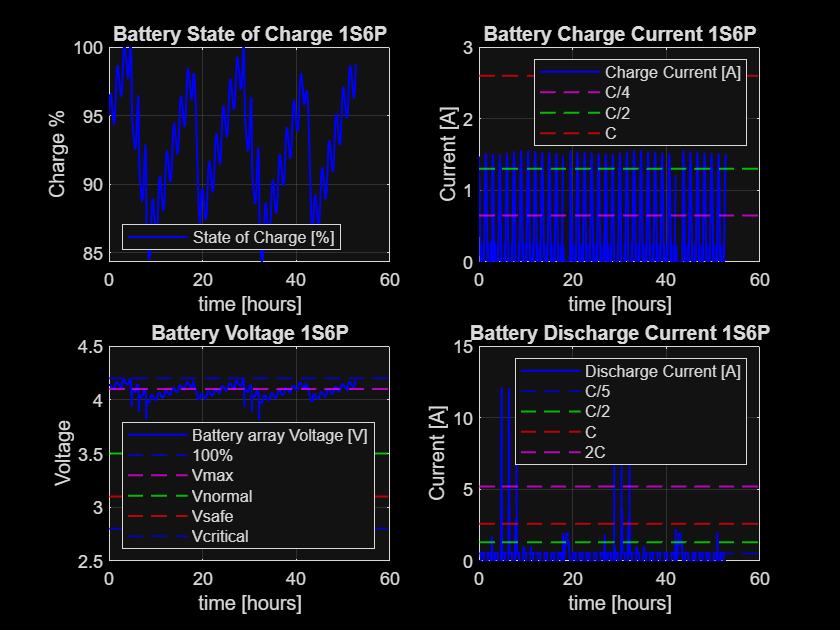

figure(10)
%set(gcf,'color','w');
set(gcf,'color','black');
    subplot(2,2,1)
        plot(time,SOC,'b','LineWidth',1)
        hold on;
        legend('State of Charge [%]')
        legend('Location','southwest')
        title(['Battery State of Charge ', num2str(Bat.Nbs),'S', num2str(Bat.Nbp),'P'])
        ylabel('Charge %')
        xlabel('time [hours]')
        grid on
subplot(2,2,2)
        plot(time,ibc,'b','LineWidth',1)
        hold on;
        yline(0.65, 'm--', 'LineWidth', 1);
        yline(1.3, 'g--', 'LineWidth', 1);
        yline(2.6, 'r--', 'LineWidth', 1);
        legend('Charge Current [A]','C/4','C/2','C')
        %title('1S 4P Battery Charge Current')
        title(['Battery Charge Current ', num2str(Bat.Nbs),'S', num2str(Bat.Nbp),'P'])
        ylabel('Current [A]')
        xlabel('time [hours]')
        grid on

subplot(2,2,3)
        plot(time,Vbat,'b','LineWidth',1)
        hold on;
        yline(4.2, 'b--', 'LineWidth', 1);
        yline(4.1, 'm--', 'LineWidth', 1);
        yline(3.5, 'g--', 'LineWidth', 1);
        yline(3.1, 'r--', 'LineWidth', 1);
        yline(2.8, 'b--', 'LineWidth', 1);
        legend('Battery array Voltage [V]','100%','Vmax','Vnormal','Vsafe','Vcritical')
        legend('Location','southwest')
        %title('1S 4P Battery Voltage')
        title(['Battery Voltage ', num2str(Bat.Nbs),'S', num2str(Bat.Nbp),'P'])
        ylabel('Voltage')
        xlabel('time [hours]')
        grid on

subplot(2,2,4)
        plot(time,ibd,'b','LineWidth',1)
        yline(0.52, 'b--', 'LineWidth', 1);
        yline(1.3, 'g--', 'LineWidth', 1);
        yline(2.6, 'r--', 'LineWidth', 1);
        yline(5.2, 'm--', 'LineWidth', 1);
        hold on;
        legend('Discharge Current [A]','C/5','C/2','C','2C')
        %title('1S 4P Battery Discharge Current')
        title(['Battery Discharge Current ', num2str(Bat.Nbs),'S', num2str(Bat.Nbp),'P'])
        ylabel('Current [A]')
        xlabel('time [hours]')
        grid on